imds = imageDatastore("Railway")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Railway\131004959_171473721383413_8222187747086021011_n.jpg';
                              ' ...\Railway\131051004_382613492830631_1306891331783850055_n.jpg';
                              ' ...\Railway\131065180_999185033824671_7735147288489715620_n.jpg'
                               ... and 318 more
                              }
                     Folders: {
                              'C:\Users\Usamah\Documents\Railwaytrackcrack\Railway'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


groundtruth = readtable("rails_edited.csv")

groundtruth = 321×2 table
                               filepaths                                  labels    
    _______________________________________________________________    _____________

    {'131004959_171473721383413_8222187747086021011_n.jpg'        }    {'Defective'}
    {'131051004_382613492830631_1306891331783850055_n.jpg'        }    {'Defective'}
    {'131065180_999185033824671_7735147288489715620_n.jpg'        }    {'Defective'}
    {'131084537_190751489449739_279862595635733772_n.jpg'         }    {'Defective'}
    {'131092897_149705809860659_8798464983059531038_n.jpg'        }    {'Defective'}
    {'131098429_134147575143001_1246437012995704959_n.jpg'        }    {'Defective'}
    {'131129946_140815574232570_8925999503657494497_n.jpg'        }    {'Defective'}
    {'131275810_2686956714949012_5021348409242545922_n.jpg'       }    {'Defective'}
    {'131348023_405054987354853_8834671660058234194_n.j

imds.Labels = categorical(groundtruth.labels)

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Railway\131004959_171473721383413_8222187747086021011_n.jpg';
                              ' ...\Railway\131051004_382613492830631_1306891331783850055_n.jpg';
                              ' ...\Railway\131065180_999185033824671_7735147288489715620_n.jpg'
                               ... and 318 more
                              }
                     Folders: {
                              'C:\Users\Usamah\Documents\Railwaytrackcrack\Railway'
                              }
                      Labels: [Defective; Defective; Defective ... and 318 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatast

classes = categories(imds.Labels)

classes = 2×1 cell array
    {'Defective'    }
    {'Non defective'}


imshow(readimage(imds,1))

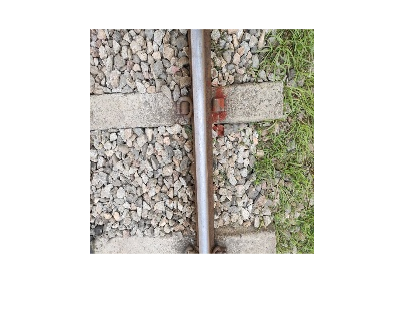

imshow(readimage(imds,2))

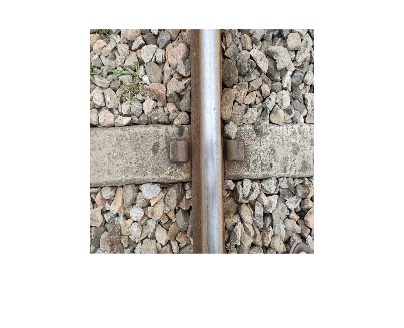

imshow(readimage(imds,3))

[trainimds,testimds] = splitEachLabel(imds,0.8,"randomized")

trainimds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Railway\131004959_171473721383413_8222187747086021011_n.jpg';
                              ' ...\Railway\131051004_382613492830631_1306891331783850055_n.jpg';
                              ' ...\Railway\131065180_999185033824671_7735147288489715620_n.jpg'
                               ... and 254 more
                              }
                     Folders: {
                              'C:\Users\Usamah\Documents\Railwaytrackcrack\Railway'
                              }
                      Labels: [Defective; Defective; Defective ... and 254 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readD

testimds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Railway\131084537_190751489449739_279862595635733772_n.jpg';
                              ' ...\Railway\131129946_140815574232570_8925999503657494497_n.jpg';
                              ' ...\Documents\Railwaytrackcrack\Railway\Broken_railroad_tracks_1.jpg'
                               ... and 61 more
                              }
                     Folders: {
                              'C:\Users\Usamah\Documents\Railwaytrackcrack\Railway'
                              }
                      Labels: [Defective; Defective; Defective ... and 61 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @read

augmenter = imageDataAugmenter( ...
    'RandRotation', [-10, 10], ...
    'RandXTranslation', [-5, 5], ...
    'RandYTranslation', [-5, 5], ...
    'RandXScale', [0.8, 1.2], ...
    'RandYScale', [0.8, 1.2]);

trainds = augmentedImageDatastore([224 224],trainimds,"DataAugmentation",augmenter)

trainds =   augmentedImageDatastore with properties:

             NumObservations: 257
                       Files: {257×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: [1×1 imageDataAugmenter]
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


testds = augmentedImageDatastore([224 224],testimds,"DataAugmentation",augmenter)

testds =   augmentedImageDatastore with properties:

             NumObservations: 64
                       Files: {64×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: [1×1 imageDataAugmenter]
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


net = imagePretrainedNetwork("resnet18",NumClasses=numel(classes))

net =   dlnetwork with properties:

         Layers: [70×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]
     Learnables: [82×3 table]
          State: [40×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.


opts = trainingOptions("adam","Metrics","accuracy","VerboseFrequency",1,"MaxEpochs",15,"InitialLearnRate",0.001,"Plots","training-progress")

opts =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 15
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 1
                  ValidationData: []
             ValidationFrequency: 50
              Validat

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingAccuracy
    _________    _____    ___________    _________    ____________    ________________
            1        1       00:00:33        0.001          2.1008              48.438
            2        1       00:01:06        0.001          1.5627              66.406
            3        2       00:01:32        0.001          2.1155              60.156
            4        2       00:02:00        0.001         0.54341              85.938
            5        3       00:02:20        0.001         0.82395              76.562
            6        3       00:02:47        0.001         0.48681              84.375
            7        4       00:03:09        0.001         0.51646              85.938
            8        4       00:03:31        0.001         0.25707                87.5
            9        5       00:03:55        0.001         0.12844               93.75
           10        5       00:04:21      

           29       15       00:11:24        0.001        0.021911              98.438
           30       15       00:11:48        0.001        0.013114                 100
Training stopped: Max epochs completed


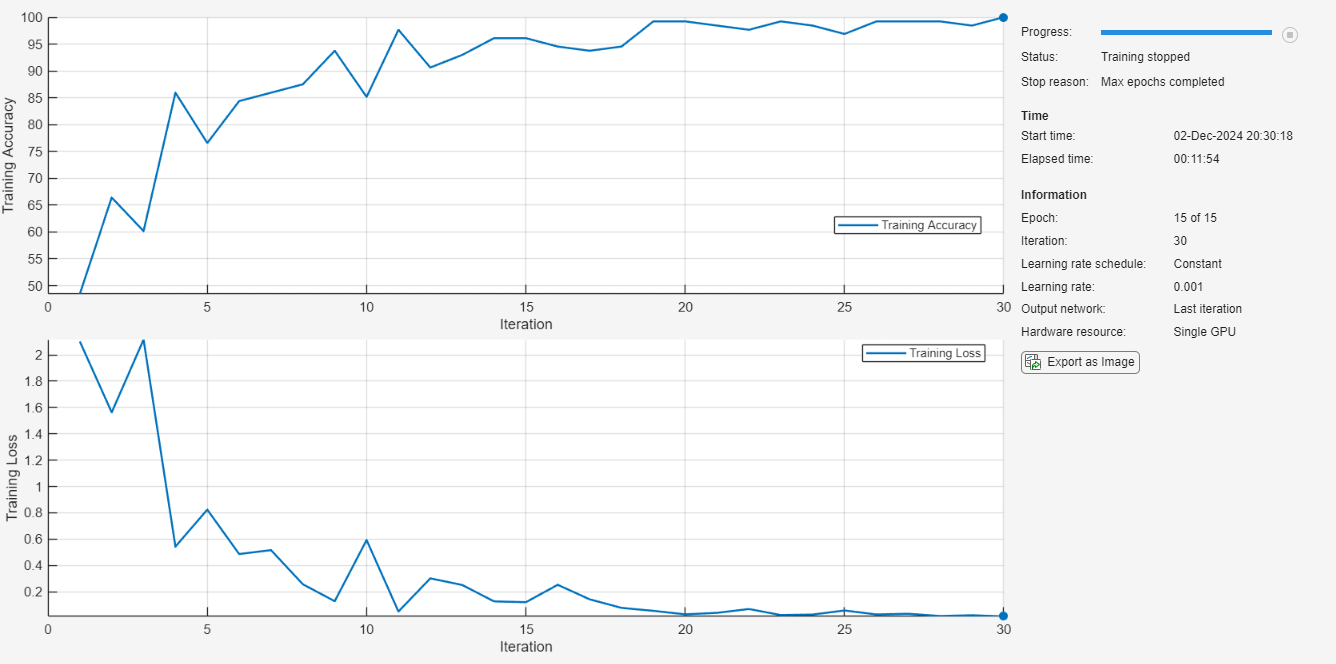

cracknet =   dlnetwork with properties:

         Layers: [70×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]
     Learnables: [82×3 table]
          State: [40×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.


info =   TrainingInfo with properties:

           TrainingHistory: [30×5 table]
         ValidationHistory: [0×0 table]
    OutputNetworkIteration: 30
                StopReason: "Max epochs completed"


[cracknet,info] = trainnet(trainds,net,"crossentropy",opts)